clear;close all
% filepath='C:[...]';
% test_Accuracy=zeros(1,4);

for k=1:4
clearvars -except filepath k
load([filepath 'TrainData' int2str(k) '.mat']);
load([filepath 'TestData' int2str(k) '.mat'])

Xtrain=TrainData.y_train{:,:}; Xtrain_nl=Xtrain;
Ytrain=TrainData.Ju_train;
Xtest=TestData.y_test{:,:}; Xtest_nl=Xtest;
Ytest=TestData.Ju_test;
ny=size(Xtrain,2);
nl_train=[];
nl_test=[];
for j=[-1,1,2]
    for r=[-1,1,2]
        if j+r>3 || j+r<-1
            continue
        end
        for i=1:ny-1
            nl_train=[nl_train,Xtrain(:,i).^j.*Xtrain(:,i+1:end).^r];
            nl_test=[nl_test,Xtest(:,i).^j.*Xtest(:,i+1:end).^r];
%             sp=Xtrain(:,i).*Xtrain(:,i+1:end);
        end
    end
end
Xtrain_nl=[Xtrain,Xtrain.^(-1),Xtrain.^2,Xtrain.^3,nl_train];
Xtest_nl=[Xtest,Xtest.^(-1),Xtest.^2,Xtest.^3,nl_test];

Xtrain_nl_norm=(Xtrain_nl-min(Xtrain_nl))./range(Xtrain_nl);
Xtest_nl=(Xtest_nl-min(Xtrain_nl))./range(Xtrain_nl);

maxNumComp = size(Xtrain_nl,2);

## PCR

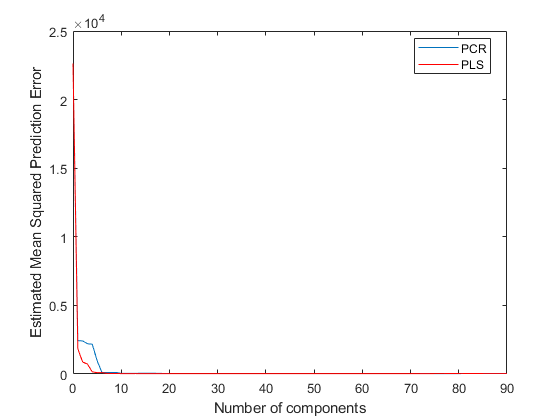

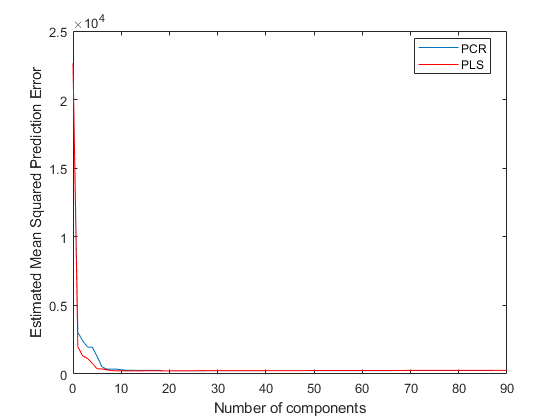

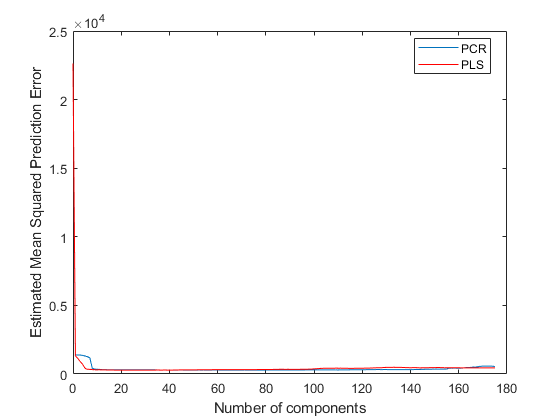

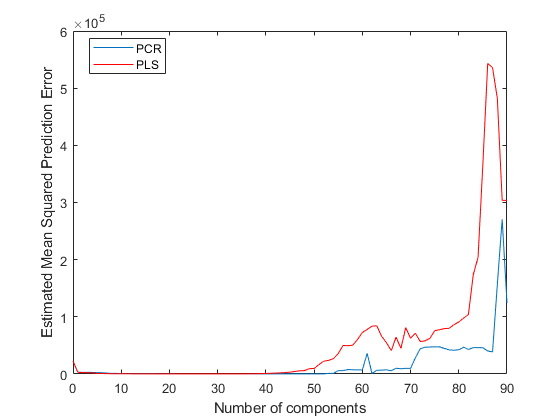

PCRmsep = sum(crossval(@pcrsse,Xtrain_nl_norm,Ytrain,'KFold',10),1) / length(Ytrain);

mseplot=figure;
plot(0:maxNumComp,PCRmsep);

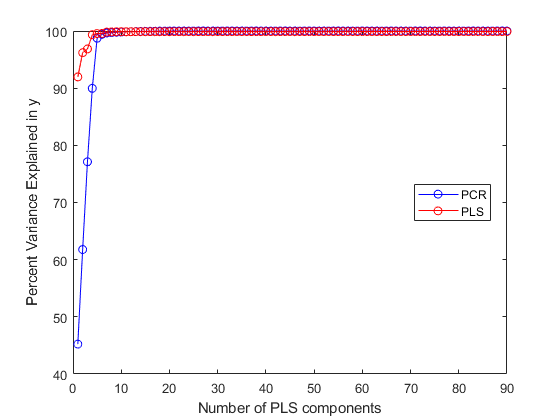

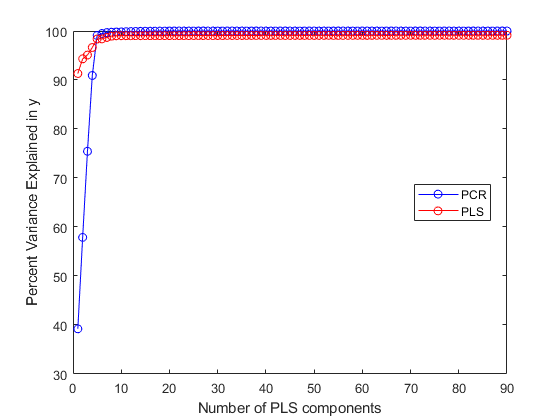

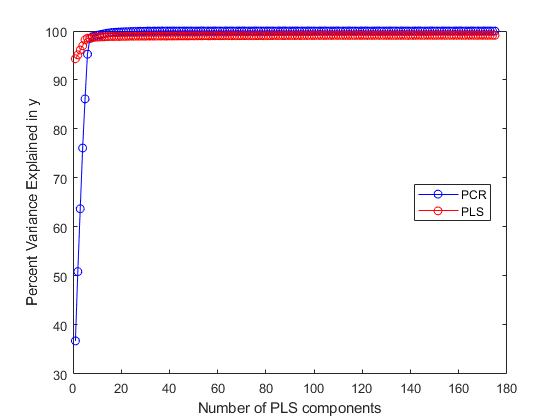

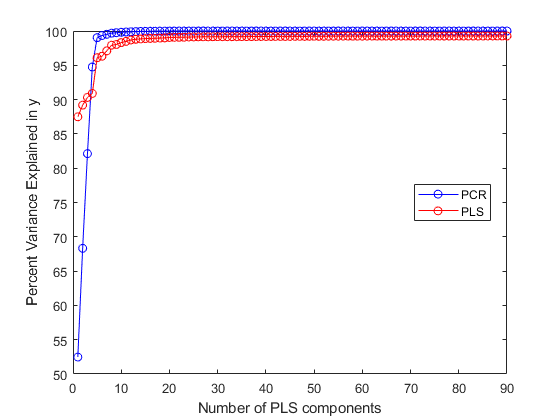

xlabel('Number of components');
ylabel('Estimated Mean Squared Prediction Error');
hold on

yfit0 = mean(Ytrain);
[Loadings,Scores,Var] = pca(Xtrain_nl_norm,'Economy',false);
beta = regress(Ytrain-yfit0, Scores(:,1:maxNumComp));

perc=figure;
plot(1:maxNumComp,100*cumsum(Var(1:maxNumComp))/sum(Var(1:maxNumComp)),'-bo');

xlabel('Number of PCR components');
ylabel('Percent Variance Explained in y');
hold on

ncomp=7;

beta0 = Loadings(:,1:ncomp)*beta(1:ncomp);
beta1 = [yfit0 - mean(Xtrain_nl_norm)*beta0; beta0];


Ypred_train = prediction_pcr_plsr(beta1,Xtrain_nl_norm);
Ypred_test = prediction_pcr_plsr(beta1,Xtrain_nl_norm);
f=calcErr(Ypred_test,Ytest);
test_Accuracy_PCR(k)=f.RMSE;

PCRresults=struct('model',beta1,'Ypred_train',Ypred_train,'Ypred_test',Ypred_test,'test_Accuracy',test_Accuracy_PCR);
% clear figu;close all


## PLSR

[~,~,~,~,betaPLS,Var,MSE] = plsregress(Xtrain_nl_norm,Ytrain,maxNumComp,'CV',10);

figure(mseplot)
plot(0:maxNumComp,MSE(2,:),'r');
xlabel('Number of components');
ylabel('Estimated Mean Squared Prediction Error');
legend('PCR','PLS','Location',"best")

figure(perc)
plot(1:maxNumComp,cumsum(100*Var(2,:)),'-ro');
xlabel('Number of PLS components');
ylabel('Percent Variance Explained in y');
legend('PCR','PLS','Location',"best")

ncomp=5;

[Xloadings,Yloadings,~,~,beta1] = plsregress(Xtrain_nl_norm,Ytrain,ncomp,'CV',10);


Ypred_train = prediction_pcr_plsr(beta1,Xtrain_nl_norm);
Ypred_test = prediction_pcr_plsr(beta1,Xtrain_nl_norm);
f=calcErr(Ypred_test,Ytest);
test_Accuracy_PLS(k)=f.RMSE;

PLSresults=struct('model',beta1,'Ypred_train',Ypred_train,'Ypred_test',Ypred_test,'test_Accuracy',test_Accuracy_PLS);


## SVR

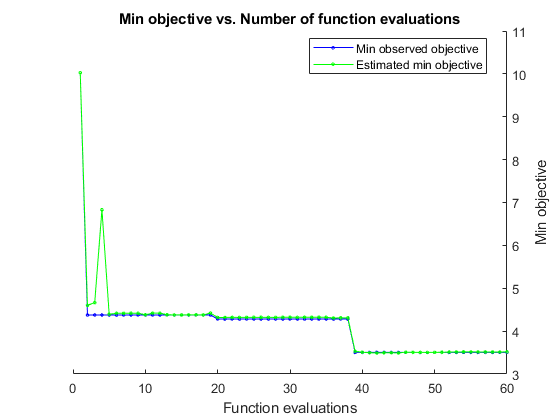

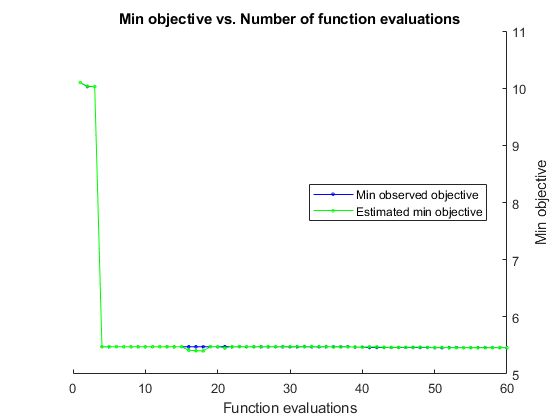

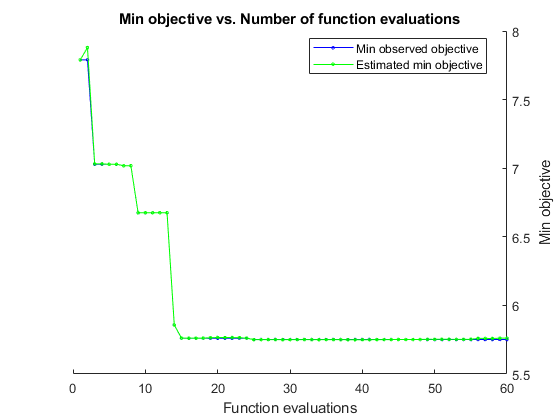

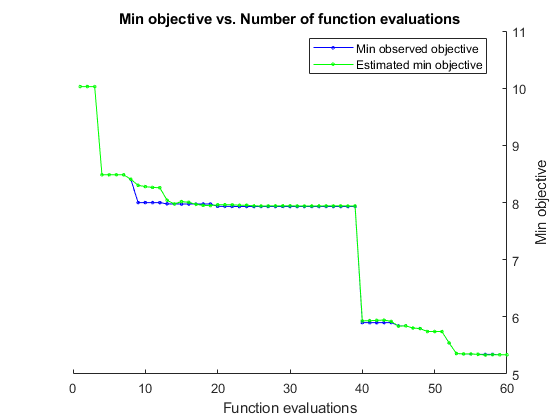

opt=struct('UseParallel',0,'Kfold',30,'Verbose',0,'ShowPlots',1,'MaxObjectiveEvaluations',40);
trainedModel=fitrsvm(Xtrain,Ytrain,'Standardize',1,'OptimizeHyperparameters','all','HyperparameterOptimizationOptions',opt);


Ypred_train = predict(trainedModel,Xtrain);
Ypred_test = predict(trainedModel,Xtest);
f=calcErr(Ypred_test,Ytest);
test_Accuracy_SVR(k)=f.RMSE;

SVRresults=struct('model',trainedModel,'Ypred_train',Ypred_train,'Ypred_test',Ypred_test,'test_Accuracy',test_Accuracy_SVR);
% load(['result_all' int2str(k)],'-mat','SVRresults')
save(['result_all' int2str(k) '.mat'],"PCRresults","PLSresults","SVRresults","Xtrain","Ytrain")

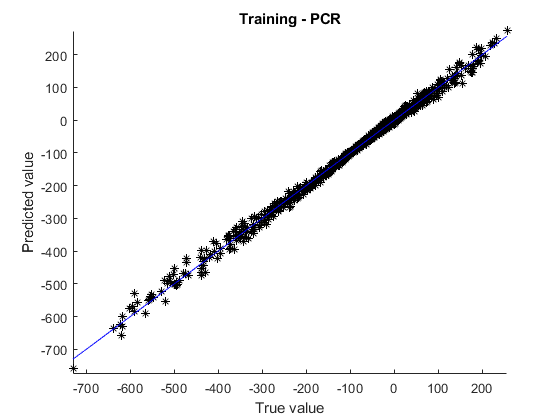

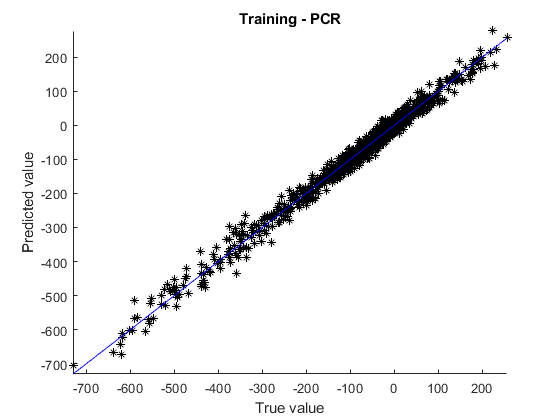

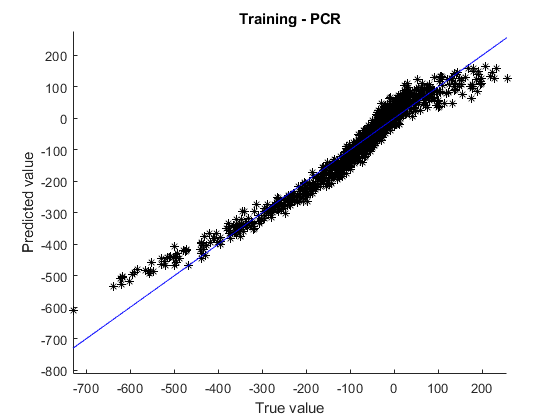

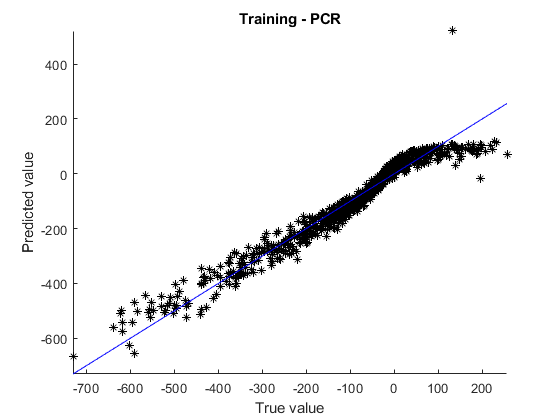

figu1=figure;
% subplot(2,3,1)
hold on
plot(Ytrain, PCRresults.Ypred_train,'k*');
plot(sort(Ytrain),sort(Ytrain), 'b')
title('Training - PCR')
xlim([min(Ytrain) max(Ytrain)])
ylim([min([Ytrain; PCRresults.Ypred_train;PLSresults.Ypred_train;SVRresults.Ypred_train]) max([Ytrain; PCRresults.Ypred_train;PLSresults.Ypred_train;SVRresults.Ypred_train])])
xlabel('True value');
ylabel('Predicted value');
saveas(figu1,[pwd '\figures\Train_PCR' int2str(k) '.fig'])

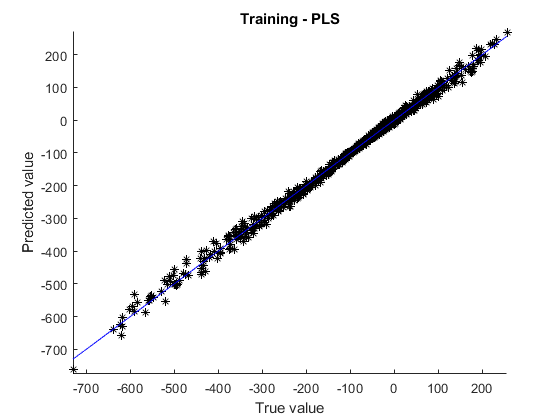

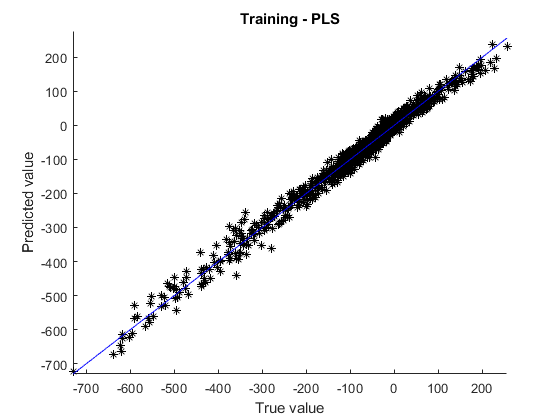

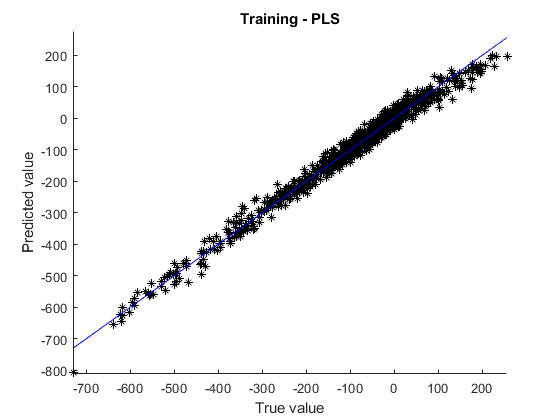

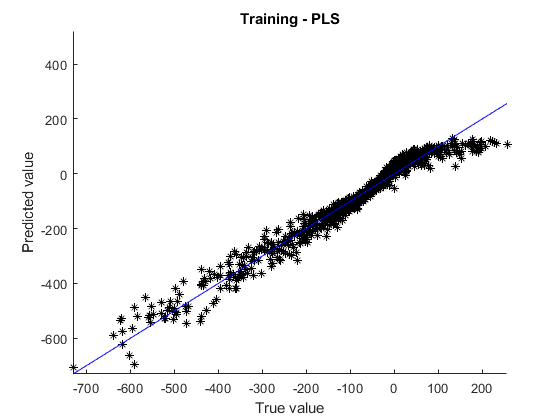

saveas(figu1,[pwd '\figures\Train_PCR' int2str(k) '.jpg'])

figu2=figure;
% subplot(2,3,2)
hold on
plot(Ytrain, PLSresults.Ypred_train,'k*');
plot(sort(Ytrain),sort(Ytrain), 'b')
title('Training - PLS')
xlim([min(Ytrain) max(Ytrain)])
ylim([min([Ytrain; PCRresults.Ypred_train;PLSresults.Ypred_train;SVRresults.Ypred_train]) max([Ytrain; PCRresults.Ypred_train;PLSresults.Ypred_train;SVRresults.Ypred_train])])
xlabel('True value');
ylabel('Predicted value');
saveas(figu2,[pwd '\figures\Train_PLS' int2str(k) '.fig'])

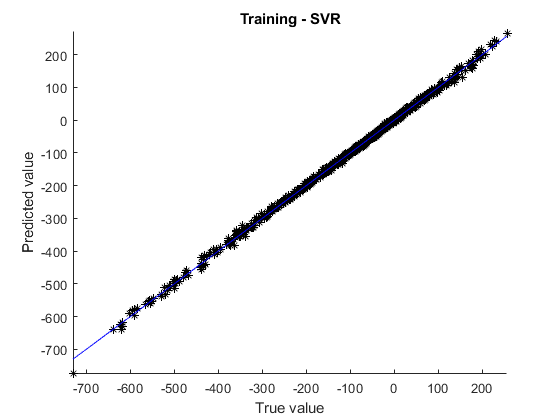

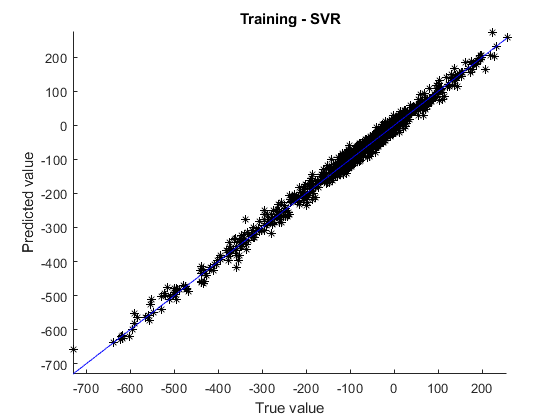

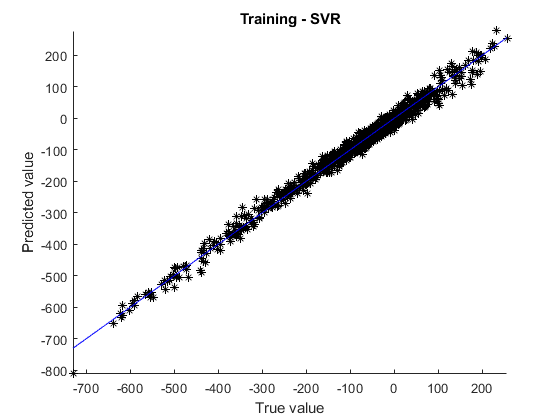

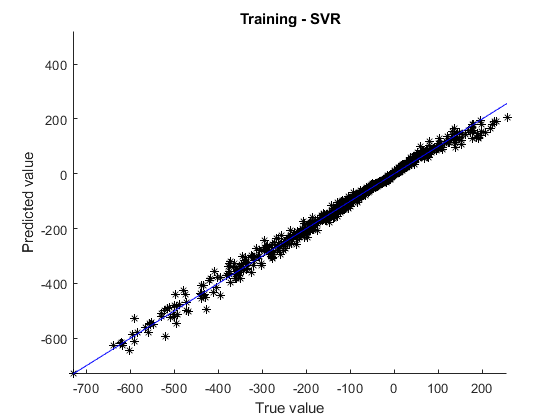

saveas(figu2,[pwd '\figures\Train_PLS' int2str(k) '.jpg'])

figu3=figure;
% subplot(2,3,3)
hold on
plot(Ytrain,SVRresults.Ypred_train,'k*');
plot(sort(Ytrain),sort(Ytrain), 'b')
title('Training - SVR')
xlim([min(Ytrain) max(Ytrain)])
ylim([min([Ytrain; PCRresults.Ypred_train;PLSresults.Ypred_train;SVRresults.Ypred_train]) max([Ytrain; PCRresults.Ypred_train;PLSresults.Ypred_train;SVRresults.Ypred_train])])
xlabel('True value');
ylabel('Predicted value');
saveas(figu3,[pwd '\figures\Train_SVR' int2str(k) '.fig'])

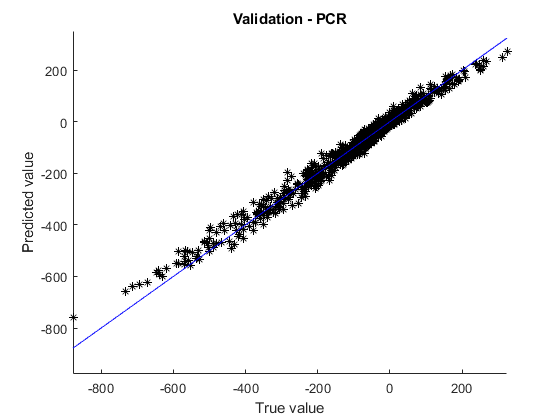

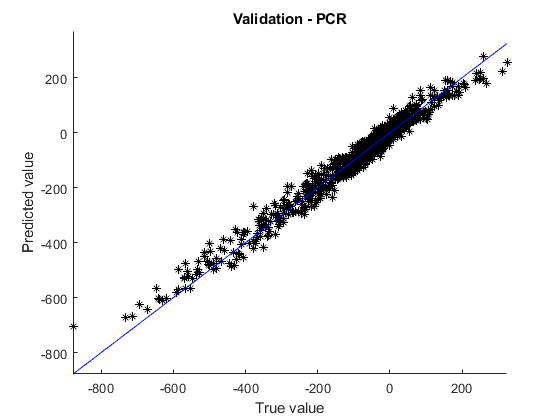

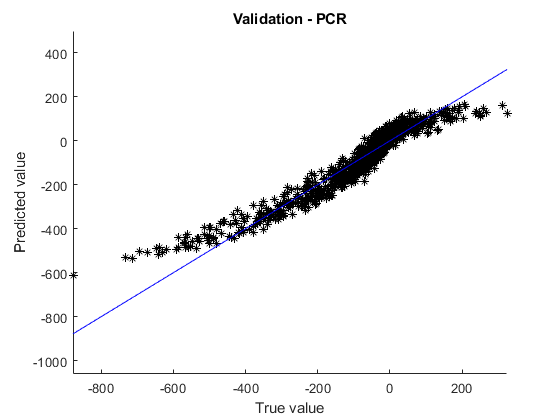

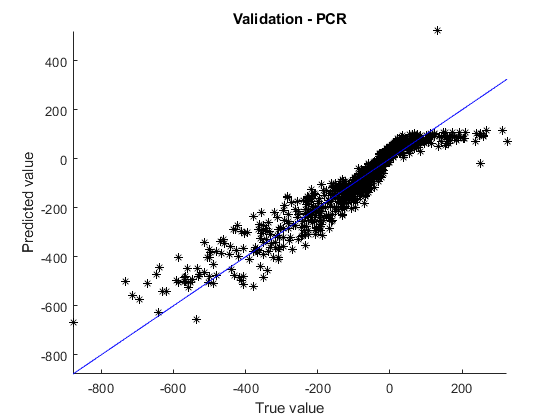

saveas(figu3,[pwd '\figures\Train_SVR' int2str(k) '.jpg'])


figu4=figure;
% subplot(2,3,4)
hold on
plot(Ytest, PCRresults.Ypred_test,'k*');
plot(sort(Ytest),sort(Ytest), 'b')
title('Validation - PCR')
xlim([min(Ytest) max(Ytest)])
ylim([min([Ytest; PCRresults.Ypred_test;PLSresults.Ypred_test;SVRresults.Ypred_test]) max([Ytest; PCRresults.Ypred_test;PLSresults.Ypred_test;SVRresults.Ypred_test])])
xlabel('True value');
ylabel('Predicted value');
saveas(figu4,[pwd '\figures\Test_PCR' int2str(k) '.fig'])

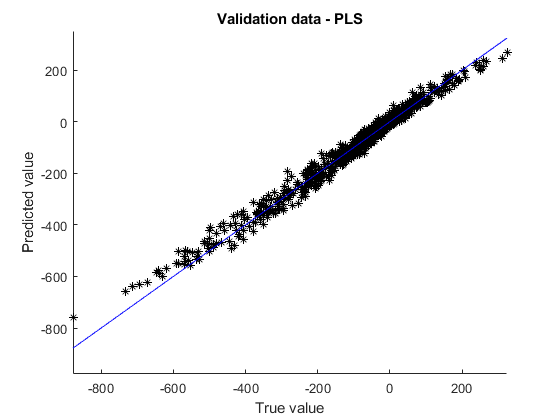

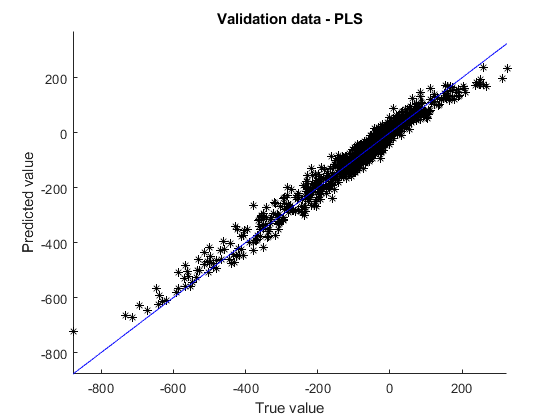

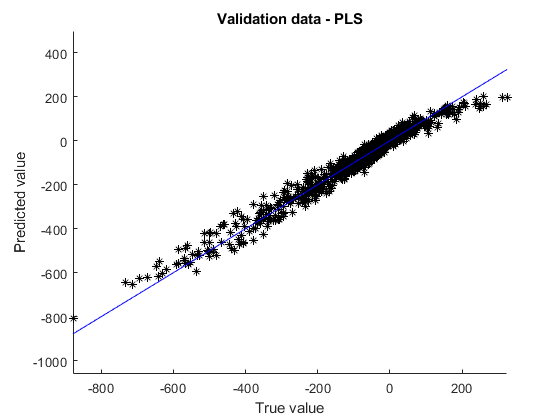

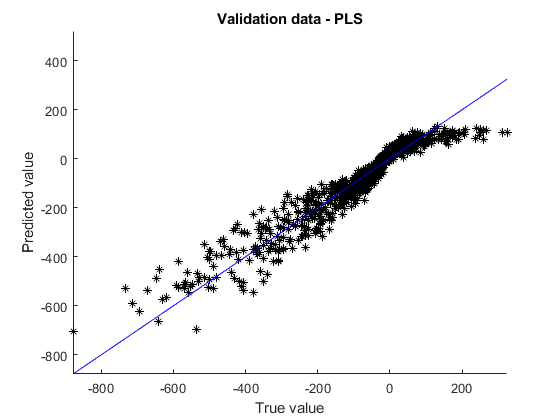

saveas(figu4,[pwd '\figures\Test_PCR' int2str(k) '.jpg'])

figu5=figure;
% subplot(2,3,5)
hold on
plot(Ytest, PLSresults.Ypred_test,'k*');
plot(sort(Ytest),sort(Ytest), 'b')
title('Validation data - PLS')
xlim([min(Ytest) max(Ytest)])
ylim([min([Ytest; PCRresults.Ypred_test;PLSresults.Ypred_test;SVRresults.Ypred_test]) max([Ytest; PCRresults.Ypred_test;PLSresults.Ypred_test;SVRresults.Ypred_test])])
xlabel('True value');
ylabel('Predicted value');
saveas(figu5,[pwd '\figures\Test_PLS' int2str(k) '.fig'])

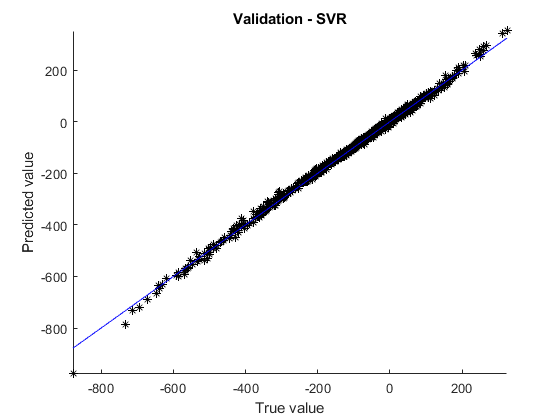

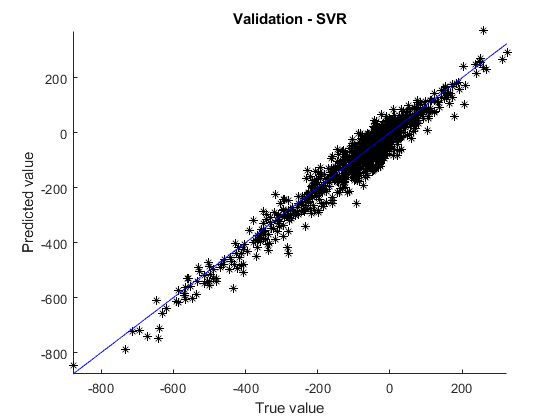

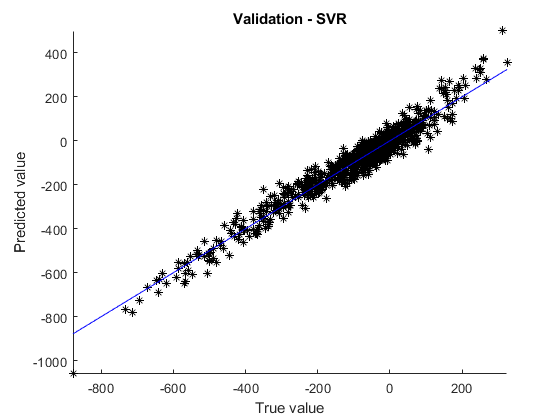

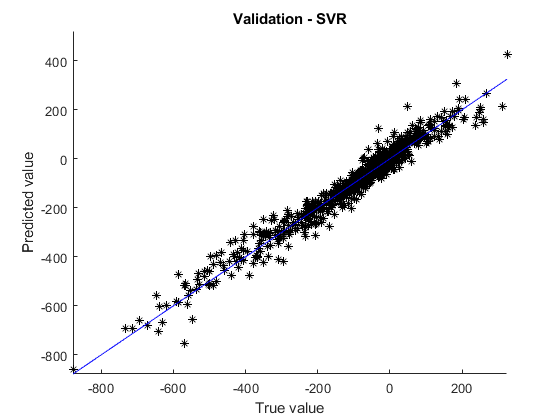

saveas(figu5,[pwd '\figures\Test_PLS' int2str(k) '.jpg'])

figu6=figure;
% subplot(2,3,6)
hold on
plot(Ytest,SVRresults.Ypred_test,'k*');
plot(sort(Ytest),sort(Ytest), 'b')
title('Validation - SVR')
xlim([min(Ytest) max(Ytest)])
ylim([min([Ytest; PCRresults.Ypred_test;PLSresults.Ypred_test;SVRresults.Ypred_test]) max([Ytest; PCRresults.Ypred_test;PLSresults.Ypred_test;SVRresults.Ypred_test])])
xlabel('True value');
ylabel('Predicted value');
saveas(figu6,[pwd '\figures\Test_SVR' int2str(k) '.fig'])

saveas(figu6,[pwd '\figures\Test_SVR' int2str(k) '.jpg'])


% saveas(figu,[pwd '\figures\Case' int2str(k) '.fig'])
% saveas(figu,[pwd '\figures\Case' int2str(k) '.jpg'])
end

function sse = pcrsse(Xtrain,ytrain,Xtest,ytest)
%PCRSSE SSE for Principal Components Regression cross-validation.
% This function is used in the demo PLSPCRDEMO.
%
% SSE = PCRSSE(XTRAIN,YTRAIN,XTEST,YTEST,NCOMP) returns a vector of sum of
% squared prediction errors for principal components regression models with
% 0:10 components, with XTRAIN and YTRAIN as training data, and XTEST and
% YTEST as test data.

%   Copyright 2008 The MathWorks, Inc.


maxNumComp = size(Xtrain,2);
sse = zeros(1,maxNumComp+1);

% The 0'th model is just the mean of the training response data.
yfit0 = mean(ytrain);
sse(1) = sum((ytest - yfit0).^2);

% Compute PCA loadings from the training predictor data, and regress the first
% 10 principal components on the centered traiing response data.
[Loadings,Scores] = pca(Xtrain,'Economy',false);
beta = regress(ytrain-yfit0, Scores(:,1:maxNumComp));


% Compute predictions for the 1st through 10th model.
for ncomp = 1:maxNumComp
    beta0 = Loadings(:,1:ncomp)*beta(1:ncomp);
    beta1 = [yfit0 - mean(Xtrain)*beta0; beta0];
    yfit = [ones(size(Xtest,1),1) Xtest]*beta1;
    sse(ncomp+1) = sum((ytest - yfit).^2);
end
end